# **Script illustrating the relationship between cone spacing and point spread function in the default cone mosaic and optics models for the treeshrew and the human visual system**

*This script illustrates the relationship between cone spacing and the PSF in the treeshrew and in the human TreeShrew cone mosaics.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Generate default human and treeshrew optics and cone mosaics

% Generate dfault optics for the treeshrew and the human
defaultTreeShewOI = oiTreeShrewCreate();
defaultHumanOI = oiCreate('wvf human');

% Generate a 1 deg tree shew cone mosaic with default params
defaultTreeShewConeMosaic = coneMosaicTreeShrewCreate(...
    defaultTreeShewOI.optics.micronsPerDegree, ...
    'fovDegs', [1 1]);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 68
Scones after making an S-cone free central patch: 68 (added Lcones:0, added Mcones:0)
Scones after pass 1: 41 (added Lcones:37, added Mcones:0)
Scones after pass 2: 24 (added Lcones:20, added Mcones:0)
Scones after pass 3: 17 (added Lcones:10, added Mcones:0)
Scones after pass 4: 13 (added Lcones:4, added Mcones:0)
Scones after pass 5: 13 (added Lcones:0, added Mcones:0)



% Generate a 0.2 deg human cone mosaic with default params
defaultHumanConeMosaic = coneMosaicHex(7, ...
    'fovDegs', [0.2 0.2]);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 103
Scones after making an S-cone free central patch: 0 (added Lcones:69, added Mcones:34)


# Step 2. Co-visualize PSFs and cone mosaics

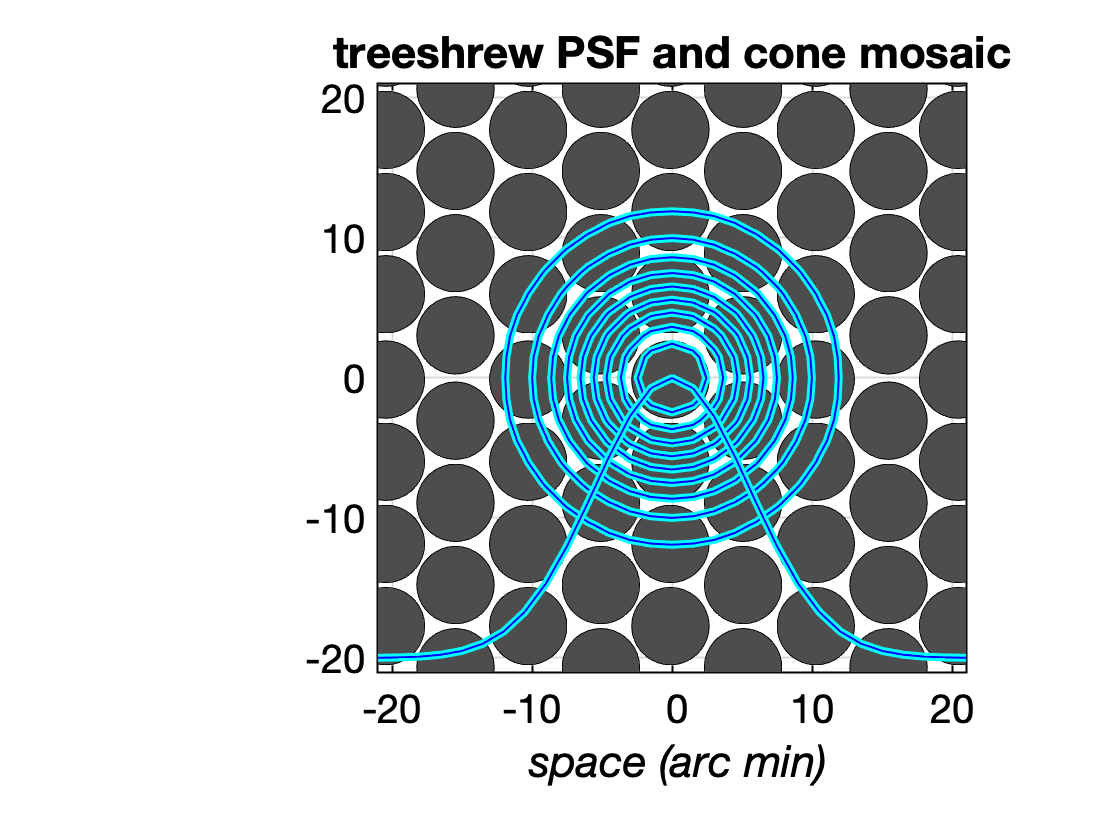

% Co-visualize the default treeshrew PSF and cone mosaic
visualizedWavelength = 550;
visualizedSpatialSupportArcMin = 40;
visualizePSF(defaultTreeShewOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultTreeShewConeMosaic, ...
    'figureTitle', 'treeshrew PSF and cone mosaic');

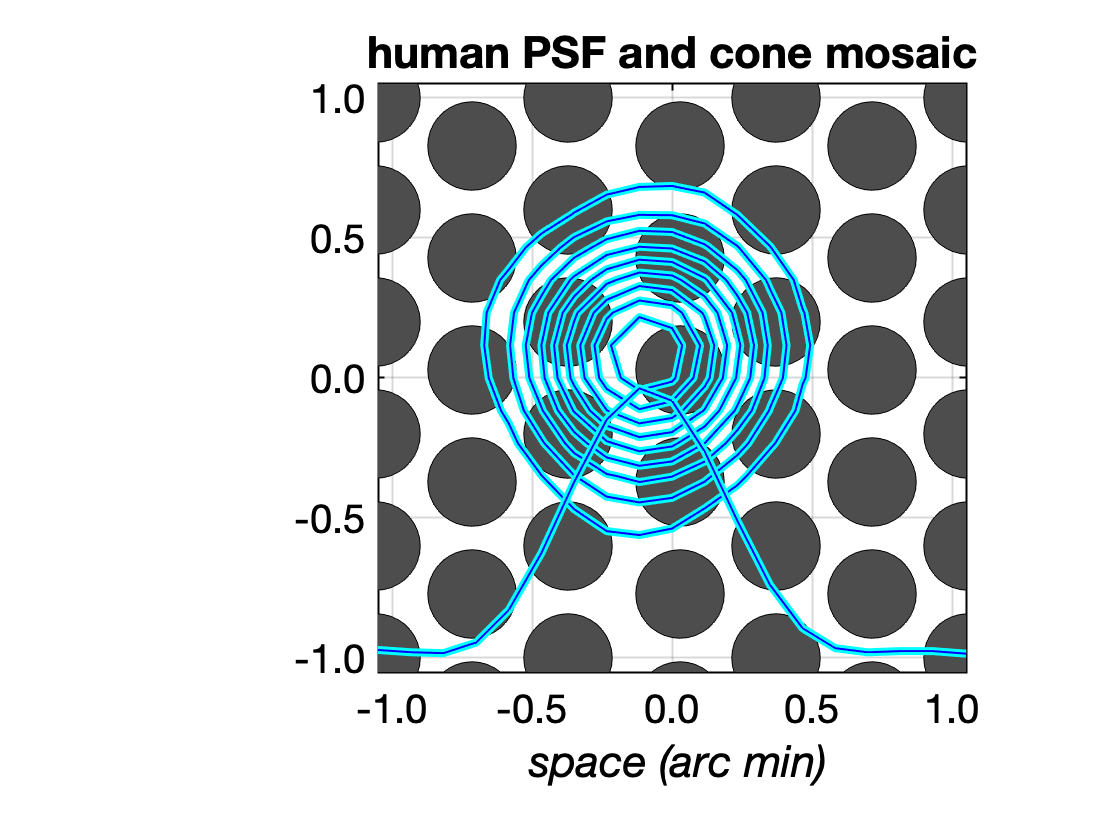


% Co-visualize the default human PSF and cone mosaic
visualizedWavelength = 550;
visualizedSpatialSupportArcMin = 2;
visualizePSF(defaultHumanOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultHumanConeMosaic, ...
    'figureTitle', 'human PSF and cone mosaic');